# pi8Gabriel Colangelo

clear
close all
clc

## Problem 3a) Maneuver to immediately return the vehicle to the Hohmann transfer path

Find: $|\Delta \bar{v}|$ and $\alpha$. Assume circular co-planar orbits. Neglect lunar mass during Earth parking orbit and transfer orbit.

**From the vector diagram, we can see that the vehicle should pass on the dark side relative to Earth,as the resultant excess velocity is in the direction towards Earth.**

From problem 2, the orbit conditions post lunar encounter are:


$$v^+ = 1.47 \ [km/s] \\
r^+ =  r_a =  384400 \ [km] \\
\gamma^+ = 33.17 \ [deg] \\
\theta^{*+} = 64.25 \ [deg] $$


However, these values were for a light side encounter. So for a dark side encounter, $\gamma^+ = -33.17 \ [deg]$ &  $\theta^{*+} = -64.25 \ [deg]$. In order to get back onto the transfer path back to the Earth parking orbit, a maneuver needs to applied such that the velocity vector post-lunar encounter is the exact same as the velocity vector prior to the lunar encounter. In other words, the velocity vector after the final maneuever needs to be equal to the velocity vector at the apoapsis of the hohmann transfer ellipse (i.e.$\bar{v}_f = \bar{v_a}= \bar{v}^-$). This will give the vehicle the appropriate orbital energy needed to get back on the same transfer ellipse it arrived on. From problem 2, the arrival velocity magnitude was $v^- =  0.1864 \ [km/s]$ with a flight path angle of $\gamma^- = 0 \ [deg]$. 

% Change in flight path angle (final is zero - apogee of transfer ellipse)
deltaFPA    = 0 - (-33.17);

% Final velocity magnitude
vf          = 0.1864;

% Post lunary flyby velocity magnitude
v_plus      = 1.47;

% Maneuver deltaV, law of cosines
dv          = sqrt(vf^2 + v_plus^2 - 2*vf*v_plus*cosd(deltaFPA));
fprintf('The required maneuver deltaV is %.3f km/s',dv)

The required maneuver deltaV is 1.318 km/s


$$|\Delta \bar{v}|^2 = v^{+2} + v_f^2 - 2v_fv^+ + \cos{\Delta \gamma} \ \text{ - Law of cosines} \\
\\
|\Delta \bar{v}| = 1.318 \ [km/s]
$$


% Calculate beta
beta        = asind(vf*sind(deltaFPA)/dv);

% Calculate alpha - increase in FPA, positive alpha
alpha       = sign(deltaFPA)*(180 - beta);
fprintf('The alpha for the maneuver is %.3f deg', alpha)

The alpha for the maneuver is 175.562 deg


$$\frac{\Delta v}{\sin{\Delta \gamma}} = \frac{v_f}{\sin{\beta}} \\

\beta = \sin^{-1}{\frac{v_f \sin{\Delta \gamma}}{\Delta v} \\


\alpha = 180 - \beta \\

\alpha = 175.56\ [deg]$$


## Problem 3b) Free Return with 174 deg Transfer Angle

Find: Time of flight, Altitude, $r_{p,moon}$, $|\Delta v_{eq}|$, $\alpha$. 

Same assumptions as problems 2 & 3a.  Periapsis of transfer ellipse is at Earth parking orbit, therefore the true anomaly on transfer ellipse when arriving at the moon is equal to the transfer angle.

% Earth Parameters
mu_earth           = 398600.4415;
R_earth            = 6378.1363;

% Moon Parameters
R_moon             = 1738.2;
mu_moon            = 4902.8005821478;

% Parking orbit altitude
alt_park           = 175;

% Parking orbit radius
r_park             = R_earth + alt_park;

% Earth Moon Orbit Radius (assume circular)
r_earth_moon       = 384400;

% Transfer angle - equal to true anomaly for this case
TA                 = 174;

% Calculate eccentricity of transfer ellipse
e_T                = (r_earth_moon - r_park)/(r_park - r_earth_moon*cosd(TA));

% Calculate semi latus rectum of transfer ellipse
p_T                = r_park*(1+e_T);

% Calculate semi major axis of transfer ellipse
a_T                = p_T/(1 - e_T^2);

% Calculate eccentric anomaly
E                  =2*atan(tand(TA/2)/sqrt((1+e_T)/(1-e_T)));

% Calculate Mean Anomaly
M                  = E - e_T*sin(E);

% Mean motion
n_T                = sqrt(mu_earth/a_T^3);

% Time of flight
TOF                = M/n_T;
fprintf('The time of flight for the Earth to Moon transfer is %.2f days',TOF/(24*3600))

The time of flight for the Earth to Moon transfer is 3.28 days


$$r_{park} = r_p = \frac{p}{1+e} \\
r_{earth,moon} = \frac{p}{1 + e \cos{\theta^*}}  \ \text{true anomaly equals transfer angle due to departure from periapsis}\\
e = \frac{r_{earth,moon} - r_{park}}{r_{park}  - r_{earth,moon} \cos{\theta^*}} = 0.972\\
p = r_{park}(1+e)  \\
a = \frac{p}{1 - e^2} = 2.1364 \times 10^5 \ [km] \\
\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e}{1-e}} ]} \\
M = E - e\sin{E} \\
M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \ \text{Initially at periapsis} \\
(t - t_p) = T.O.F =  \frac{M}{ \sqrt{\frac{\mu}{a^3}}} \\
\\
T.O.F. = 78.6 \ [hours] = 3.28 \ [days]$$


**The time of flight for this new transfer is 40.9 hours shorter than what it was for the Hohmann transfer (119.5 hours). This is due to the transfer angle being less than that of the Hohmann transfer (180 degrees).**

% Geocentric velocity of moon in circular orbit
v_moon_earth        = sqrt(mu_earth/r_earth_moon);

% Transfer ellipse energy
energy_T            = -mu_earth/(2*a_T);

% Geocentric velocity magnitude of sc at lunar arrival on transfer ellipse
v_sc_earth_mag      = sqrt(2*(energy_T + mu_earth/r_earth_moon));

% Specific angular momentum on transfer ellipse
h_T                 = sqrt(mu_earth*p_T);

% Solve for flight path angle at lunar arrival
gamma_minus         = sign(TA)*acosd(h_T/(r_earth_moon*v_sc_earth_mag));

% Geocentric velocity of sc at lunar arrival on transfer ellipse
v_sc_earth_minus    = [v_sc_earth_mag*sind(gamma_minus);v_sc_earth_mag*cosd(gamma_minus)];

% Excess velocity of s/c relative to the moon prior to flyby
v_inf_moon_minus    = v_sc_earth_minus - [0;v_moon_earth];

% Specific energy of hyperbolic orbit about moon
energy_H            = norm(v_inf_moon_minus)^2/2;

% Semi major axis of hyperbolic orbit about moon
a_abs_H             = mu_moon/(2*energy_H);

% Excess velocity of s/c relative to the moon post flyby
v_inf_moon_plus     = [-v_inf_moon_minus(1);v_inf_moon_minus(2)];

% Flyby angle - angle between new and old excess velocity vectors
delta               = acosd(dot(v_inf_moon_plus,v_inf_moon_minus)...
                      /(norm(v_inf_moon_plus)*norm(v_inf_moon_minus)));

% Eccentricity of hyperbolic orbit about moon
e_H                 = 1/sind(delta/2);

% Passage radius about moon
rp_moon             = a_abs_H*(e_H - 1);

% Passage altitude about moon
alt_moon            = rp_moon - R_moon;

fprintf(['The required passage radius is %.1f km \n',...
         'The required passage altitude is %.1f km '],rp_moon, alt_moon)

The required passage radius is 3793.1 km 
The required passage altitude is 2054.9 km 


$$v_{moon/earth} = \sqrt{\frac{\mu_{earth}}{r_{earth,moon}}} \\
\epsilon = \frac{-\mu_{earth}}{2a} \\
v^- = \sqrt{2(\epsilon + \frac{\mu_{earth}}{r_{earth,moon}})} \ \text{ - Geocentric velocity magnitude of sc at lunar arrival}\\
h = \sqrt{p\mu_{earth}} \\
\cos{\gamma^-} = \frac{h}{v^- r_{earth,moon}} \ \text{ - Positive, ascending} \\
\bar{v}^- = v^-\sin{\gamma^-} \ \hat{r} + v^-\cos{\gamma^-} \ \hat{\theta} = 0.564 \ \hat{r} + 0.187 \ \hat{\theta} \ [km/s]\\
\bar{v}_\infty^- = \bar{v}^- -\bar{v}_{moon/earth}  = 0.564 \ \hat{r} - 0.831 \ \hat{\theta} \ [km/s] \\
\bar{v}_\infty^+  = -0.564 \ \hat{r} - 0.831 \ \hat{\theta} \ [km/s] \ \text{ - Flyby doesn't change magnitude, only direction}\\
\epsilon_H = \frac{v_\infty^{-2}}{2} \ \text{ - Energy of hyperbolic orbit about moon} \\
|a| = \frac{\mu_{moon}}{2\epsilon_H} \\
\cos{\delta} = \frac{\bar{v}_\infty^+  \cdot \bar{v}_\infty^-}{|\bar{v}_\infty^+| |\bar{v}_\infty^-|} \\
\sin{\frac{\delta}{2}} = \frac{1}{e_H}\\
r_p = |a|(e_H - 1) \\
h_p = r_p - R_{moon} \ \text{ - Altitude for passage} \\
\\
r_p = 3793.1 \ [km]\\
h_p = 2054.9 \ [km]$$


% Equivalent deltaV magnitude
dv_eq               = v_inf_moon_plus - v_inf_moon_minus;
fprintf('The equivalent deltaV magnitude for the free return is %.3f km/s',norm(dv_eq))

The equivalent deltaV magnitude for the free return is 1.128 km/s


$$\Delta \bar{v}_{eq}= \bar{v}_\infty^+ - \bar{v}_\infty^- = -1.128 \ \hat{r} \ [km/s] \\
|\Delta \bar{v}_{eq}| = 1.128 \ [km/s]$$


% Geocentric velocity of sc at lunar post lunar flyby
v_sc_earth_plus     = dv_eq + v_sc_earth_minus;

% Flight path angle post lunar flyby
gamma_plus          = atan2d(v_sc_earth_plus(1),v_sc_earth_plus(2));

% Calculate beta
beta                = asind(norm(v_sc_earth_plus)*sind(abs(gamma_plus - gamma_minus))/norm(dv_eq));

% Calculate alpha - increase in FPA, positive alpha
alpha               = sign(gamma_plus - gamma_minus)*(180 - beta);
fprintf('The alpha for the free return is %.3f deg', alpha)

The alpha for the free return is -161.689 deg


$$\bar{v}^+ = \Delta \bar{v}_{eq} + \bar{v}^-\ \\
\tan{\gamma^+} =\frac{v^+_r}{v^+_{\theta} \\

\Delta \gamma = \gamma^+ - \gamma^- \\

\frac{|\Delta v_{eq}|}{\sin{\Delta \gamma}} = \frac{v^+}{\sin{\beta}} \\

\beta = \sin^{-1}{\frac{v^+ \sin{\Delta \gamma}}{|\Delta v_{eq}|} \\

\alpha = 180 - \beta \\

\alpha = -161.69 \ [deg] \ \text{ - decrease in flight path angle, negative}$$


## Problem 3c) Plot Orbits

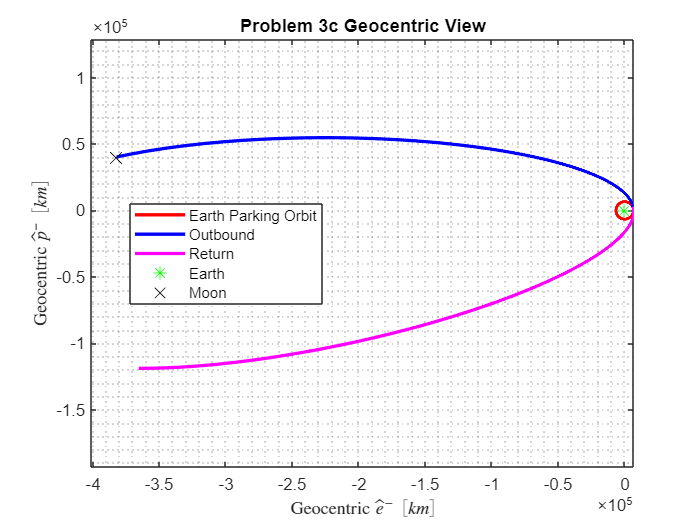

% True anomaly vector
ta_vec              = 0:.1:360;

% Initialize position vectors in perifocal frame
r_park_P            = zeros(2,length(ta_vec));
r_outbound_P        = [];
r_return_P          = [];

% Calculate new true anomaly post lunar flyby
theta_plus          = wrapTo2Pi(atan2((r_earth_moon*norm(v_sc_earth_plus)^2/mu_earth)*...
                      cosd(gamma_plus)*sind(gamma_plus),((r_earth_moon*...
                      norm(v_sc_earth_plus)^2/mu_earth)*cosd(gamma_plus)^2 - 1)))*180/pi;

% Change in arguement of periapsis
deltaAOP            = theta_plus - TA;

% Rotation matrix from new perifocal frame to original perifocal frame
Pminus_DCM_Pplus    = [cosd(deltaAOP), -sind(deltaAOP);...
                       sind(deltaAOP), cosd(deltaAOP)];

for i = 1:length(ta_vec)

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R            = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                           sind(ta_vec(i)), cosd(ta_vec(i))];

    % Outbound transfer ellipse
    if ta_vec(i) <= TA
        % Calculate transfer orbit radii
        r_outbound         = p_T/(1 + e_T*cosd(ta_vec(i)));

        % Outbound transfer orbit in perifocal coordinates
        r_outbound_P       = [r_outbound_P, P_DCM_R*[r_outbound;0]]; 

   
    % Return Arc
    else 

        % Calculate transfer orbit radii
        r_return           = p_T/(1 + e_T*cosd(theta_plus));

        % Position vector in new perifocal frame
        r_return_Pnew      = [cosd(theta_plus), -sind(theta_plus);...
                              sind(theta_plus), cosd(theta_plus)]*[r_return;0];

        % Position vector in old perifocal frame
        r_return_P          = [r_return_P, Pminus_DCM_Pplus*r_return_Pnew];

        % True anomaly in new perifocal frame
        theta_plus         = theta_plus + .1;
    end

    % Parking orbit in perifocal coordinates
    r_park_P(:,i)      = P_DCM_R*[r_park;0];
end

figure
plot(r_park_P(1,:), r_park_P(2,:),'-r','LineWidth',2)
hold on
plot(r_outbound_P(1,:), r_outbound_P(2,:),'-b','LineWidth',2)
plot(r_return_P(1,:), r_return_P(2,:),'-m','LineWidth',2)
plot(0, 0,'g*','MarkerSize',8)
plot(r_outbound_P(1,end),r_outbound_P(2,end),'kx','MarkerSize',10)
grid minor
xlabel('Geocentric $\hat{e}^- \ [km]$', 'Interpreter','latex')
ylabel('Geocentric $\hat{p}^- \ [km]$', 'Interpreter','latex')
xlim([1.05*r_outbound_P(1,end) 1.05*r_park])
axis equal
title('Problem 3c Geocentric View')
legend('Earth Parking Orbit','Outbound','Return','Earth','Moon','Location','best')

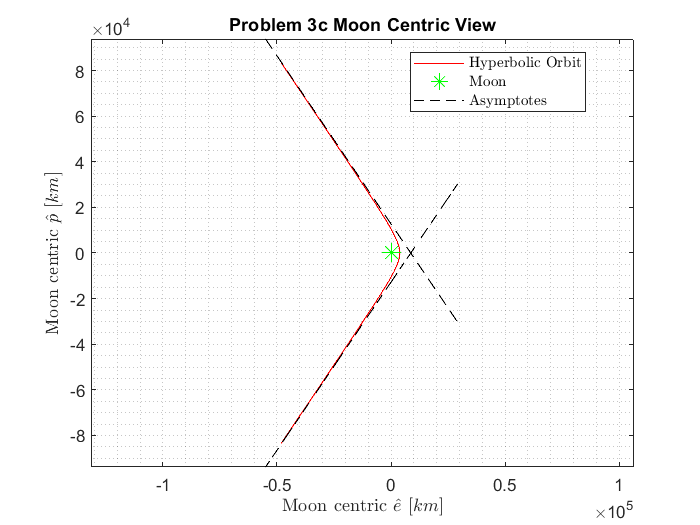

% True Anomaly Vector
ta_vec      = -120:.01:120;

% Initialize Perifocal position vector
r_H         = zeros(2,length(ta_vec)); 

% Calculate true anomaly of the asymptote
theta_inf   = acosd(-1/e_H);

for i = 1:length(ta_vec)

    % Distance to probe from moon
    r_mag     =  (a_abs_H*(e_H^2 - 1))/(1 + e_H*cosd(ta_vec(i)));

    % Position Vector in Perifocal Frame - Centered at Moon 
    r_H(:,i)  = [r_mag*cosd(ta_vec(i));r_mag*sind(ta_vec(i))]; 
end

% Slope of line
slope       = tand(theta_inf - delta);

% Create asymptote
asym        = slope*((-55000:100:30000) - a_abs_H*e_H);

figure
plot(r_H(1,:),r_H(2,:),'-r')
hold on
plot(0, 0,'g*','MarkerSize',10)
plot((-55000:100:30000), -asym,'--k')
plot((-55000:100:30000), asym,'--k')
title('Problem 3c Moon Centric View')
axis equal
grid minor
hold on
xlabel('Moon centric $\hat{e} \ [km]$', 'Interpreter','latex')
ylabel('Moon centric $\hat{p} \ [km]$', 'Interpreter','latex')
legend('Hyperbolic Orbit','Moon','Asymptotes',...
       'Location', 'best','Interpreter','latex')
hold off